clc
clearvars
close all

nlist = readtable("./data/nlist.csv");
nlist.Properties.VariableNames = {'Name','Label','Group'};
nlist.Name = string(nlist.Name);
elist_dy = readtable("./data/elist_dynamic.csv");

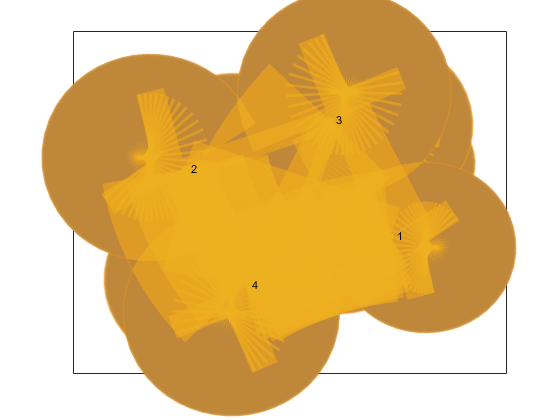

num_edges = size(elist_dy,1);
% edges = strings(num_edges,1);
snodes = elist_dy.Source;
tnodes = elist_dy.Target;

% s = {num2str(snodes(1))};
% t = {num2str(tnodes(1))};
s = snodes(1);
t = tnodes(1);
elist = [s,t];
w = 1;
etable = table(elist,w, 'VariableNames',{'EndNodes','Weight'});
% G = graph(etable,nlist);
G = graph(etable,nlist);

figure('Color','w')
plot(G,'LineWidth',etable.Weight)


for i=2:num_edges
    s = snodes(i);
    t = tnodes(i);
    [edge_exist,idx] = ismember([s,t],G.Edges.EndNodes,'rows');

    if(all(edge_exist))
        G.Edges.Weight = G.Edges.Weight+1;        
    else
        G = addedge(G,s,t,1);
%         elist = [elist; [s,t]];
%         w = [w;1];
    end
    hold on
    plot(G, 'LineWidth',G.Edges.Weight)
    drawnow
    hold off
end
% 
% endnodes = unique(edges);
% num_edges = length(endnodes);
% snodes = zeros(num_edges,1);
% tnodes = zeros(num_edges,1);
% 
% for i=1:num_edges
%     split_cha = split(endnodes(i),"");
%     snodes(i) = str2double(split_cha(2));
%     tnodes(i) = str2double(split_cha(3));
% end
% 
% weights = ones(length(endnodes),1)*0.1;
% etable = table([snodes, tnodes],weights,'VariableNames',{'EndNodes','Weight'});

snodes = elist_dy.Source;
tnodes = elist_dy.Target;
for i=1:size(elist_dy,1)
    s = snodes(i);
    t = snodes(i);
    match_idx = ismember([s,t],etable.EndNodes);

any(~match_idx)
end

% running_edges
% running_weights
% running_etable

G = graph(etable);
plot(G, 'LineWidth',etable.Weight)